# ENIGMA Toolbox Tutorial 

### ---------------------------------

### Load ENIGMA datasets

### ---------------------------------

% Load summary statistics for ENIGMA-Epilepsy
sum_stats = load_summary_stats('epilepsy');

% Get case-control subcortical volume and cortical thickness tables
SV = sum_stats.SubVol_case_vs_controls_ltle;
CT = sum_stats.CortThick_case_vs_controls_ltle;

% Extract Cohen's d values
SV_d = SV.d_icv;
CT_d = CT.d_icv;

disp(SV_d)

   -0.1020
   -0.2190
   -0.1820
   -1.7280
   -0.2690
   -0.3850
   -0.8430
    0.4650
   -0.1230
    0.2660
   -0.0630
   -0.2040
   -0.4520
   -0.2850
   -0.4620
    0.3630



### -------------------------------------

### Surface data visualization

### -------------------------------------

% Map parcellated data to the surface
CT_d_fsa5 = parcel_to_surface(CT_d, 'aparc_fsa5');

1 x 2 files to read, % remaining: 100 Done


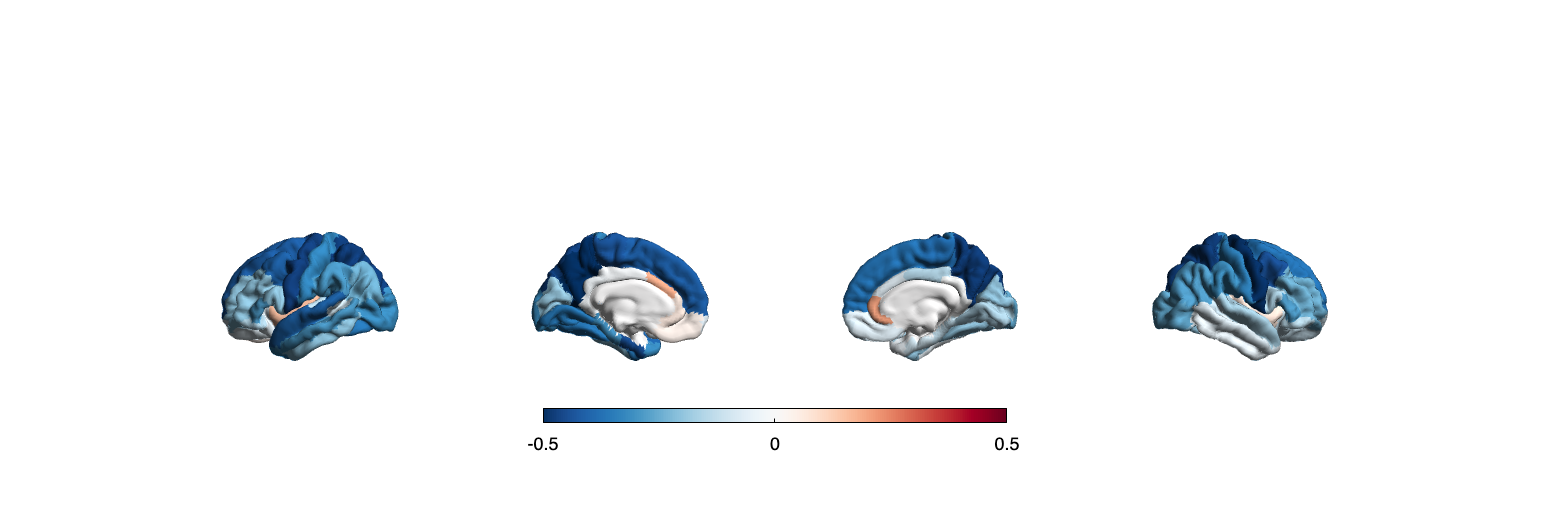

1 x 2 files to read, % remaining: 100 Done



% Project the results on the surface brain
f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_cortical(CT_d_fsa5, 'surface_name', 'fsa5', 'color_range', ...
              [-0.5 0.5], 'cmap', 'RdBu_r');

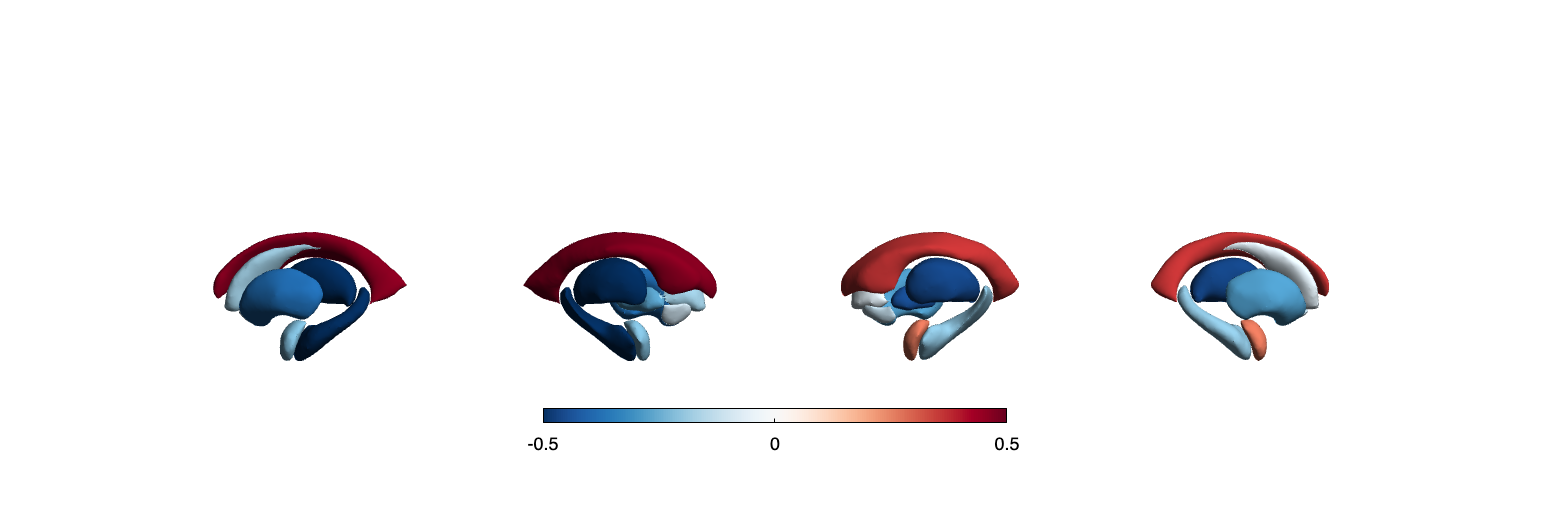

% Project the results on the surface brain
f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_subcortical(SV_d, 'color_range', [-0.5 0.5], 'cmap', 'RdBu_r');

### ----------------------------------------------

### BigBrain moments and gradient

### ----------------------------------------------

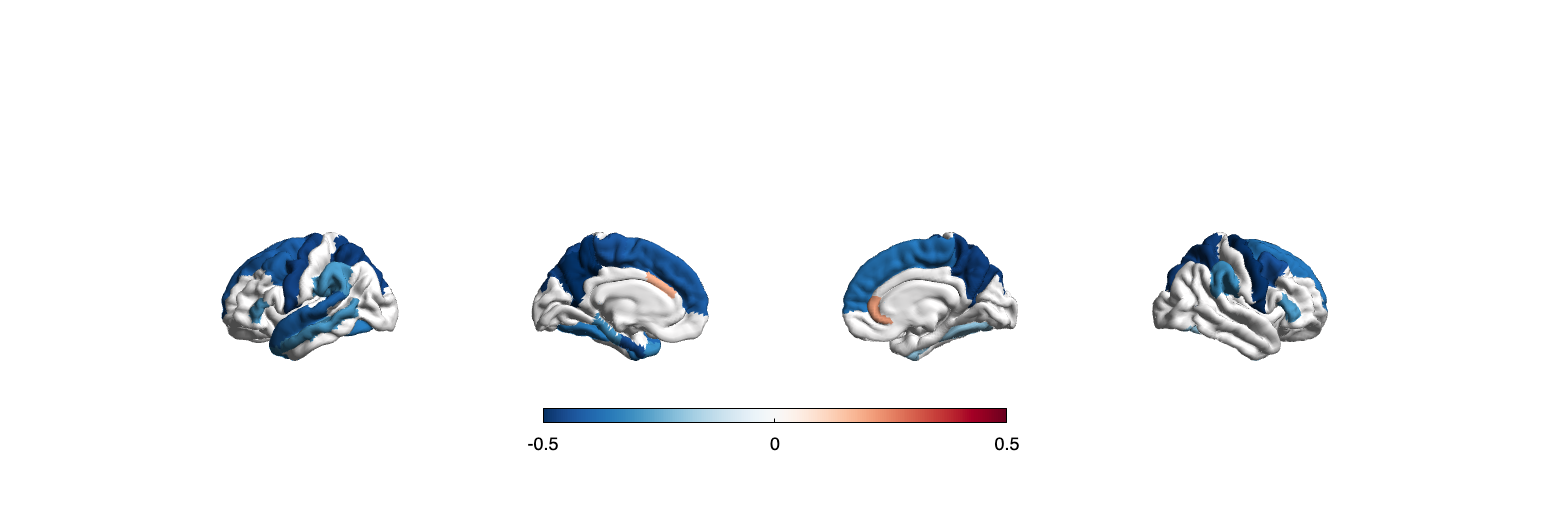

1 x 2 files to read, % remaining: 100 Done
1 x 2 files to read, % remaining: 100 Done


% Extract FDR-corrected p-values and find regions with p < 0.01
region_idx  = find(CT.fdr_p <= 0.01);

% Visualize thresholded Cohen's d map
CT_d_thr              = zeros(length(CT_d), 1);
CT_d_thr(region_idx)  = CT_d(region_idx);
f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_cortical(parcel_to_surface(CT_d_thr), 'color_range', [-0.5 0.5]);

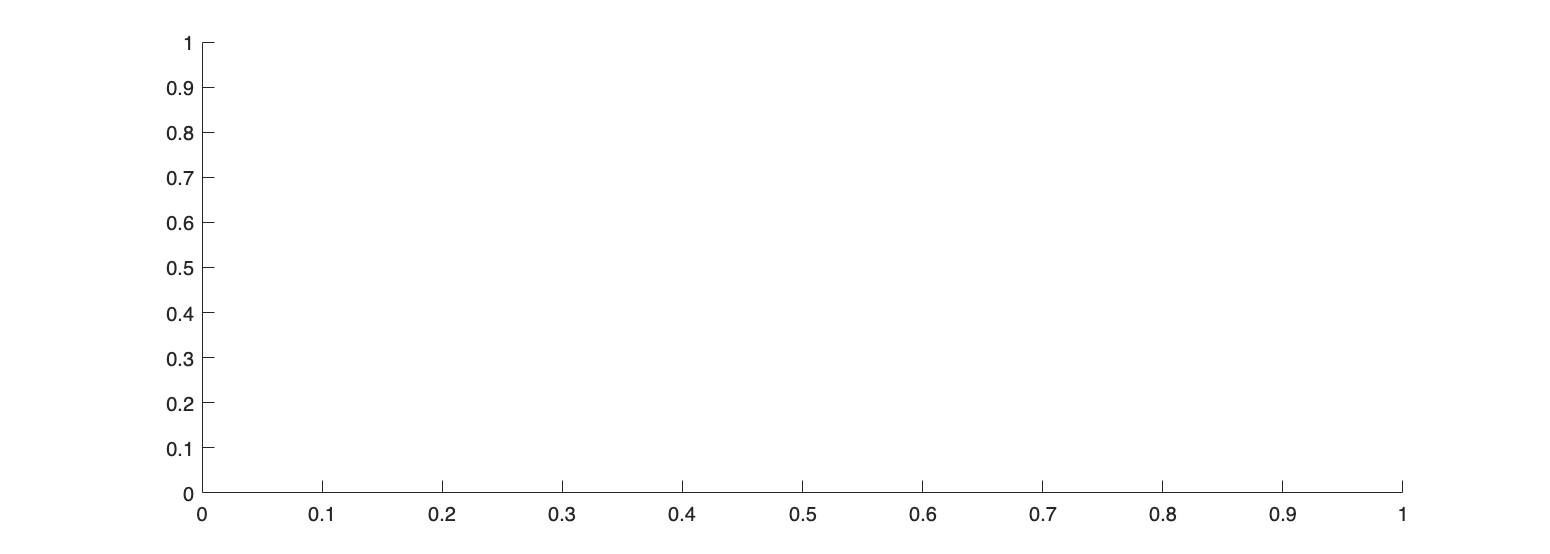

% Stratify and plot results according to BigBrain statistical moments
f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
bb_moments_raincloud(region_idx')

% Stratify and plot results according to the BigBrain gradient
CT_d_thr(CT_d_thr == 0) = nan;
f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
bb_gradient_plot(CT_d_thr, 'axis_range', [-0.6 0.25], ...
            'yaxis_label', 'Cohen'' {\it d}')

### -----------------------------------------------

### Economo-Koskinas stratification

### -----------------------------------------------

1 x 2 files to read, % remaining: 100 Done


axis_range =    -0.3487   -0.1414
   -0.3487   -0.1414
   -0.3487   -0.1414
   -0.3487   -0.1414
   -0.3487   -0.1414


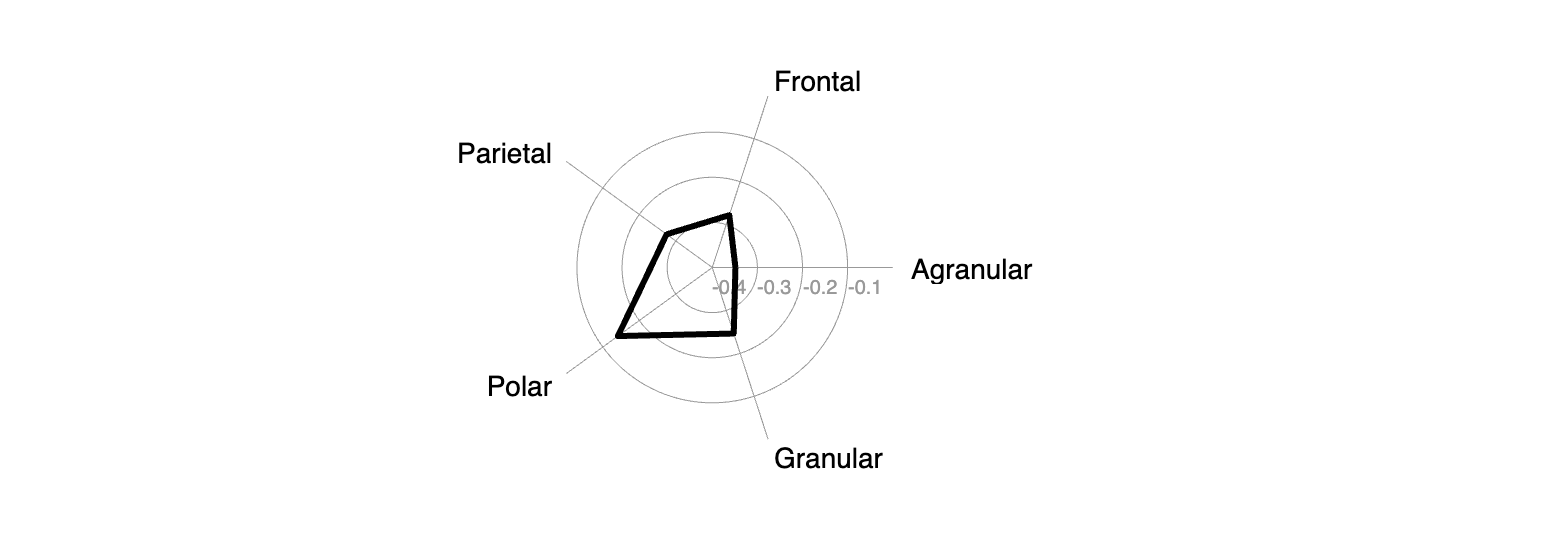

% Stratify cortical atrophy based on Economo-Koskinas classes
class_mean = economo_koskinas_spider(CT_d, 'axis_range', [-0.4 0]);

### ------------------------------------

### Hub susceptibility model

### ------------------------------------

% Load functional connectivity data
[fc_ctx, fc_ctx_labels, fc_sctx, fc_sctx_labels] = load_fc();

% Compute weighted degree centrality measures from the connectivity data
fc_ctx_dc           = sum(fc_ctx);
fc_sctx_dc          = sum(fc_sctx, 2);

% Map parcellated data to the surface
fc_ctx_dc_fsa5      = parcel_to_surface(fc_ctx_dc, 'aparc_fsa5');

1 x 2 files to read, % remaining: 100 Done


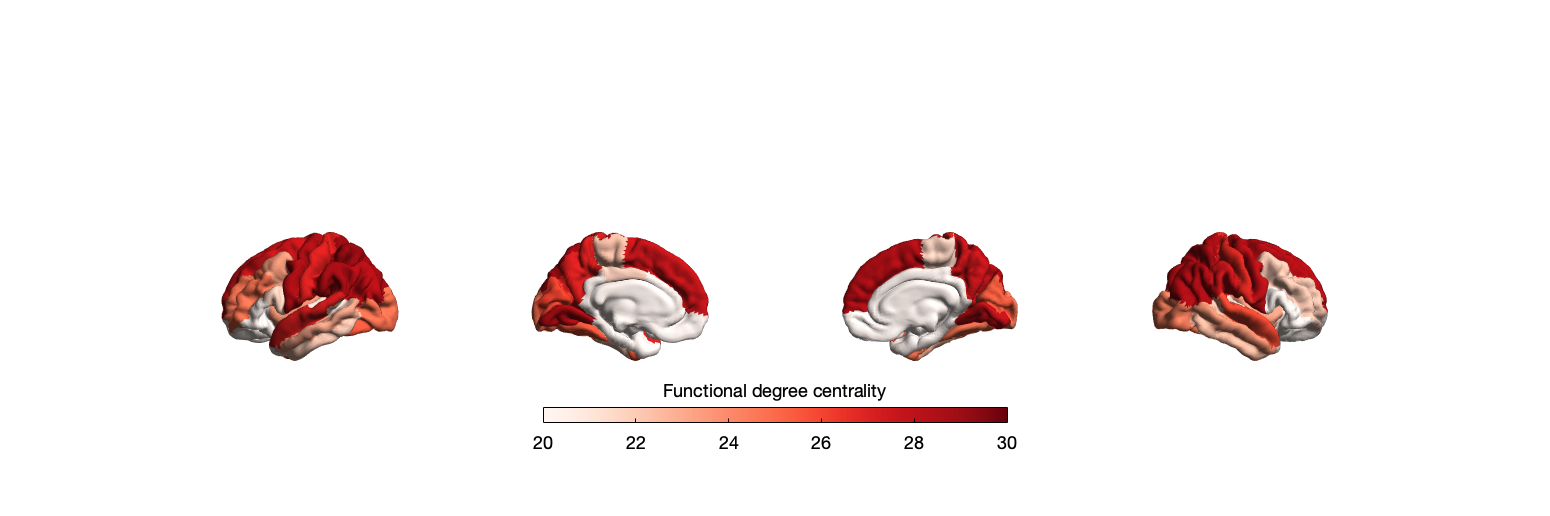

1 x 2 files to read, % remaining: 100 Done



% Project the results on the surface brain
f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_cortical(fc_ctx_dc_fsa5, 'surface_name', 'fsa5', 'color_range', [20 30], ...
            'cmap', 'Reds', 'label_text', 'Functional degree centrality');

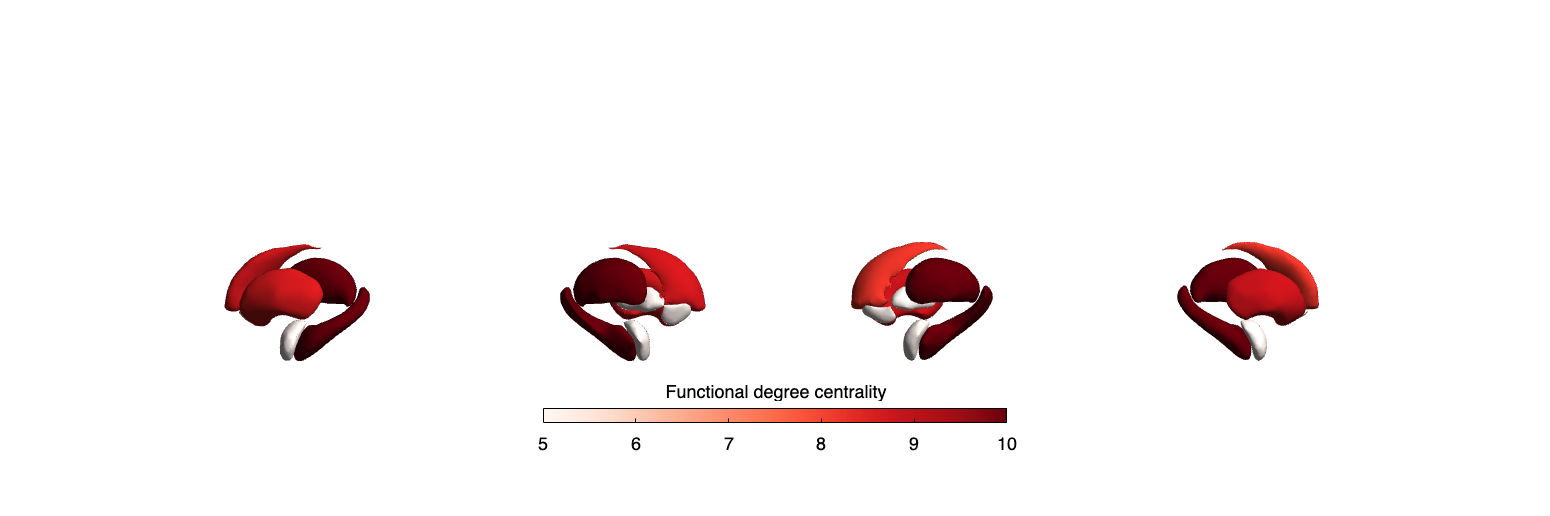


f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_subcortical(fc_sctx_dc, 'ventricles', 'False', 'color_range', [5 10], ...
               'cmap', 'Reds', 'label_text', 'Functional degree centrality');

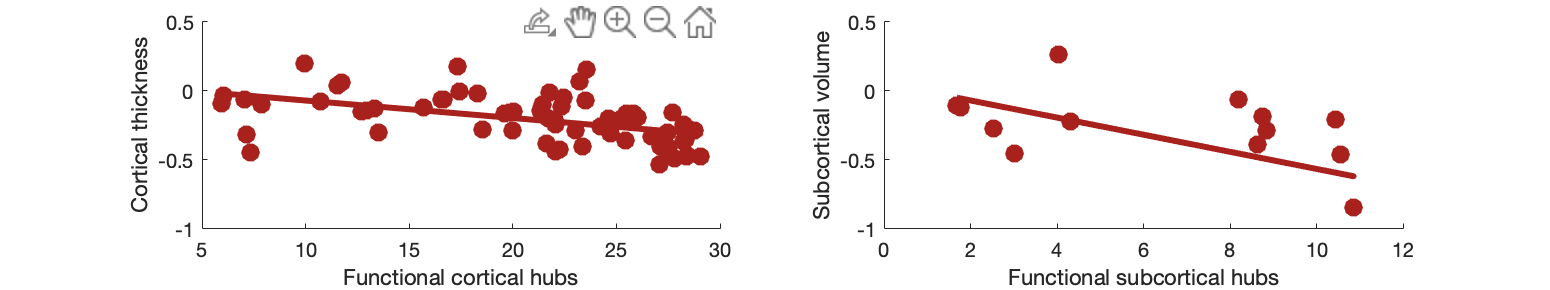


% Remove subcortical values corresponding the ventricles
% (as we don't have connectivity values for them!)
SV_d_noVent = SV_d;
SV_d_noVent([find(strcmp(SV.Structure, 'LLatVent')); ...
            find(strcmp(SV.Structure, 'RLatVent'))], :) = [];

% Perform spatial correlations between cortical hubs and Cohen's d
fc_ctx_r = corrcoef(fc_ctx_dc, CT_d);

% Perform spatial correlations between structural hubs and Cohen's d
fc_sctx_r = corrcoef(fc_sctx_dc, SV_d_noVent);

% Store correlation coefficients
rvals = cell2struct({fc_ctx_r(1, 2), fc_sctx_r(1, 2)}, ...
    {'functional_cortical_hubs', 'functional_subcortical_hubs'}, 2);

% Store degree centrality measures
meas  =  cell2struct({fc_ctx_dc.', fc_sctx_dc}, ...
                     {'Functional_cortical_hubs', 'Functional_subcortical_hubs'}, 2);
fns   = fieldnames(meas);

% Store atrophy measures
meas2 =  cell2struct({CT_d, SV_d_noVent}, {'Cortical_thickness', 'Subcortical_volume'}, 2);
fns2  = fieldnames(meas2);

f = figure;
set(gcf,'color','w');
set(gcf,'units','normalized','position',[0 0 1 0.3])

for k = 1:numel(fieldnames(meas))

    % Define plot colors
    col = [0.66 0.13 0.11];

    % Plot relationships between hubs and atrophy
    axs = subplot(1, 2, k); hold on
    s   = scatter(meas.(fns{k}), meas2.(fns2{k}), 88, col, 'filled');
    P1      = polyfit(meas.(fns{k}), meas2.(fns2{k}), 1);
    yfit_1  = P1(1) * meas.(fns{k}) + P1(2);
    plot(meas.(fns{k}), yfit_1, 'color',col, 'LineWidth', 3)
    ylim([-1 0.5])
    xlabel(strrep(fns{k}, '_', ' '))
    ylabel(strrep(fns2{k}, '_', ' '))
end

### ---------------------------------

### Spin permutation tests

### ---------------------------------

% Spin permutation testing for two cortical maps
[fc_ctx_p, fc_ctx_d]   = spin_test(fc_ctx_dc, CT_d, 'surface_name', 'fsa5', ...
    'parcellation_name', 'aparc', 'n_rot', 1000, 'type', 'pearson');

Reading from version 2
colortable with 36 entries read (originally /autofs/space/amaebi_026/users/buckner_cortical_atlas/scripts/colortable_final.txt)
Reading from version 2
colortable with 36 entries read (originally /autofs/space/amaebi_026/users/buckner_cortical_atlas/scripts/colortable_final.txt)
permutation 100 of 1000
permutation 200 of 1000
map to itself n.1
permutation 300 of 1000
permutation 400 of 1000
permutation 500 of 1000
permutation 600 of 1000
permutation 700 of 1000
permutation 800 of 1000
permutation 900 of 1000
permutation 1000 of 1000


% Store p-values and null distributions
p_and_d =  cell2struct({[fc_ctx_p; fc_ctx_d]}, {'functional_cortical_hubs'}, 2);

f = figure;
set(gcf,'color','w');
set(gcf,'units','normalized','position',[0 0 1 0.3])
fns = fieldnames(p_and_d);

% Define plot colors
col = [0.66 0.13 0.11]

col =     0.6600    0.1300    0.1100


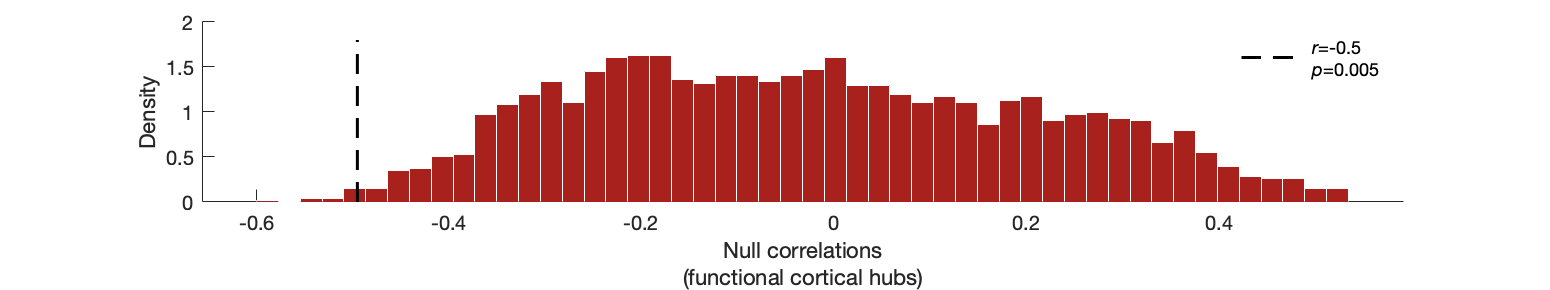


% Plot null distributions
hold on
h = histogram(p_and_d.functional_cortical_hubs(2:end), 50, ...
    'Normalization', 'pdf', 'edgecolor', 'w', 'facecolor', ...
    col, 'facealpha', 1, 'linewidth', 0.5);
l = line([rvals.functional_cortical_hubs rvals.functional_cortical_hubs], ...
    get(gca, 'ylim'), 'linestyle', '--', 'color', 'k', 'linewidth', 1.5);
xlabel(['Null correlations' newline '(' strrep('functional_cortical_hubs', '_', ' ') ')'])
ylabel('Density')
legend(l,['{\it r}=' num2str(round(rvals.functional_cortical_hubs, 2)) newline ...
    '{\it p}=' num2str(round(p_and_d.functional_cortical_hubs(1), 3))])
legend boxoff